# Ex 11

## 1) see in file perdecomp.m

## 2)

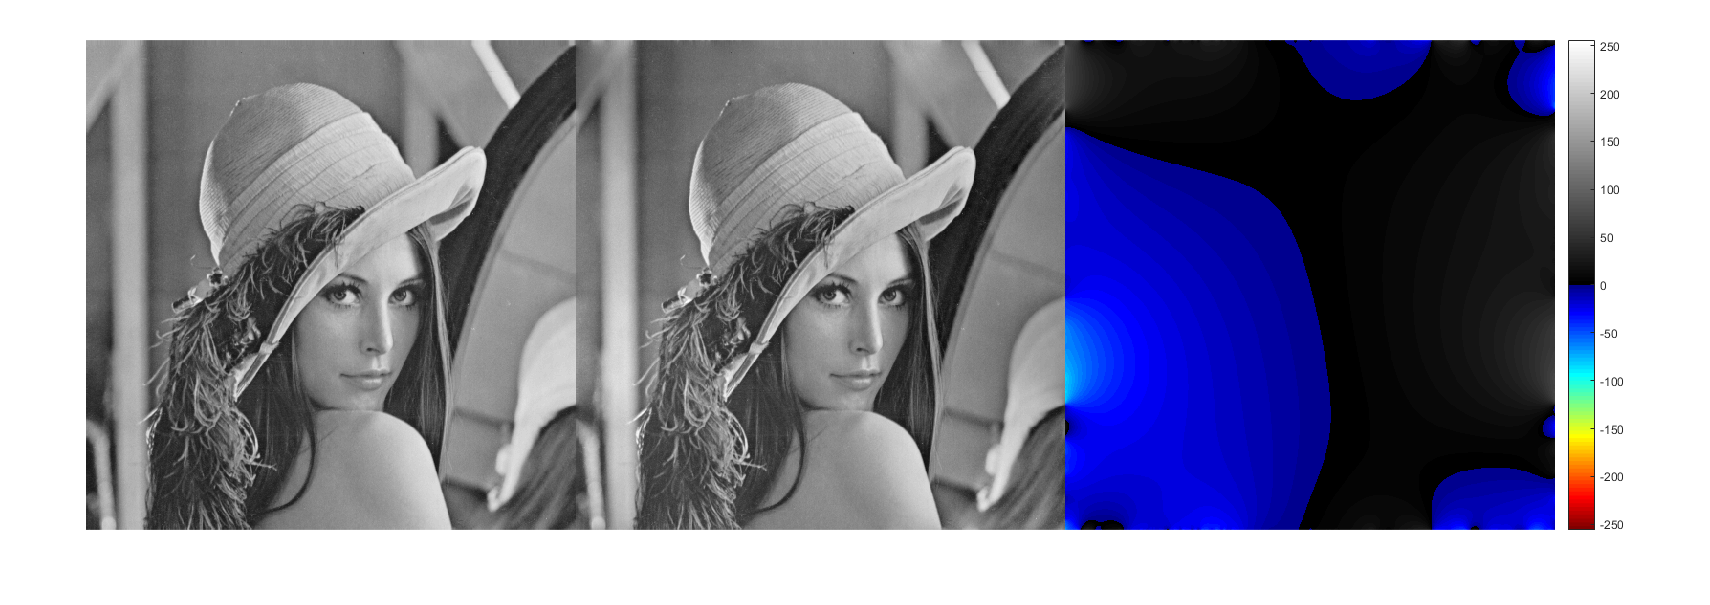

u = double(imread('lena.pgm'));
[p,s]=perdecomp(u);
cmap = vertcat(flipud(jet),gray);
% we visualize u,p,s together, 
% and mark negative value
% using another colorbar
imshow([u,p,s],[-256,256]);
colormap(gca,cmap);
colorbar


fprintf('error=%e',max(max(abs(p+s-u))));

error=2.842171e-14

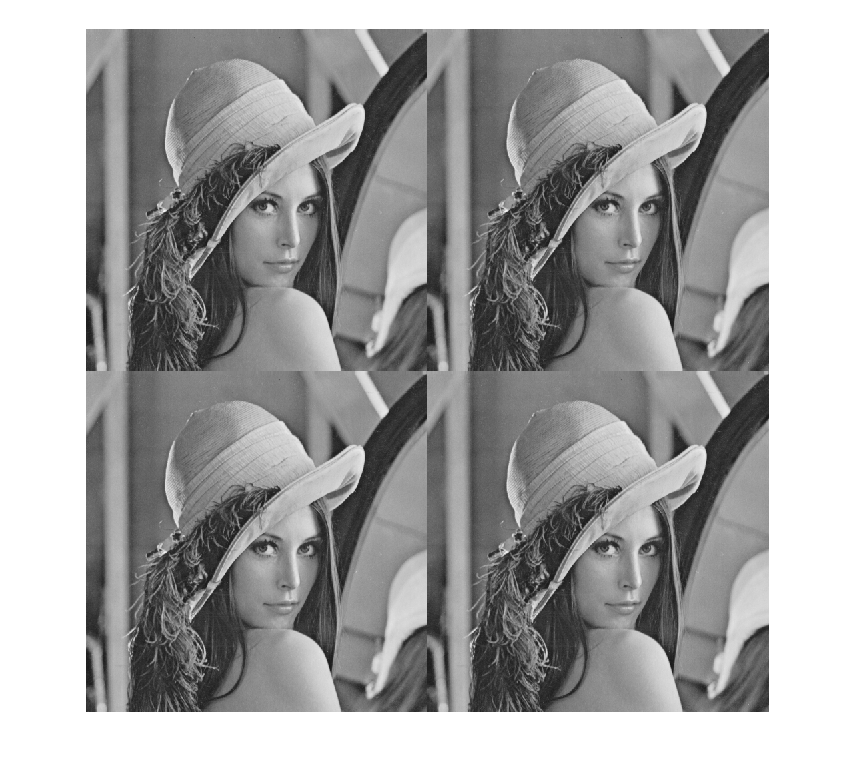


imshow(kron(ones(2,2),u),[0,256]);

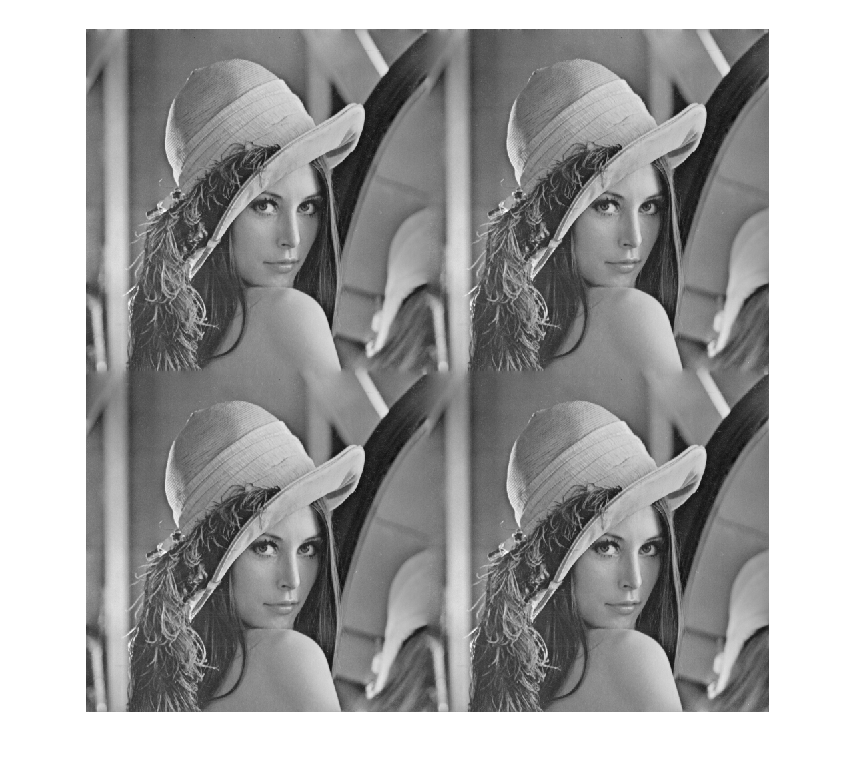

imshow(kron(ones(2,2),p),[0,256]);

imshow(kron(ones(2,2),s),[-100,100]);

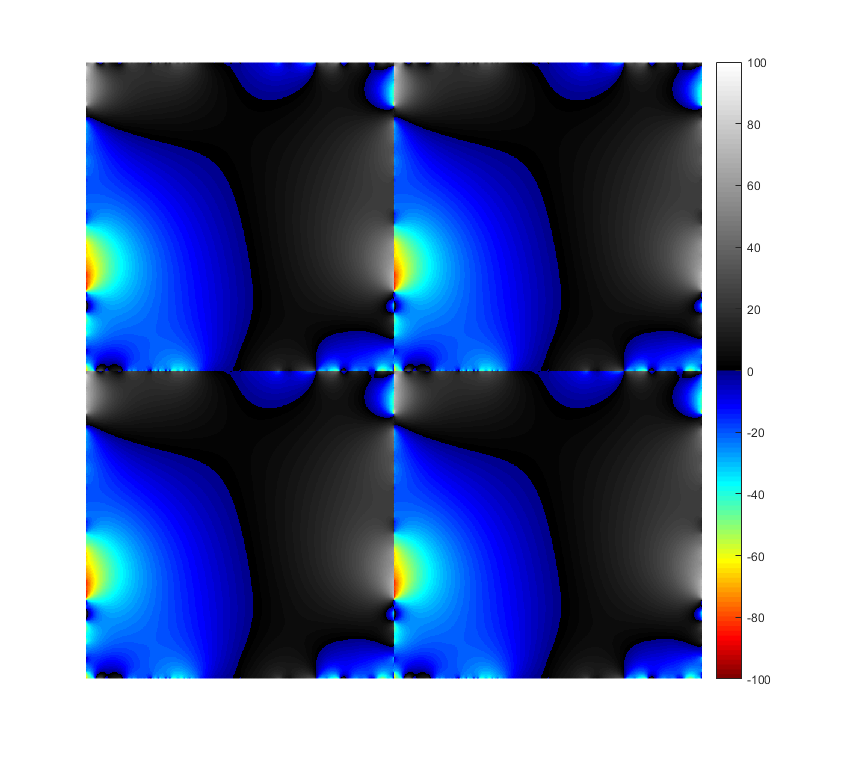

colormap(gca,cmap);
colorbar

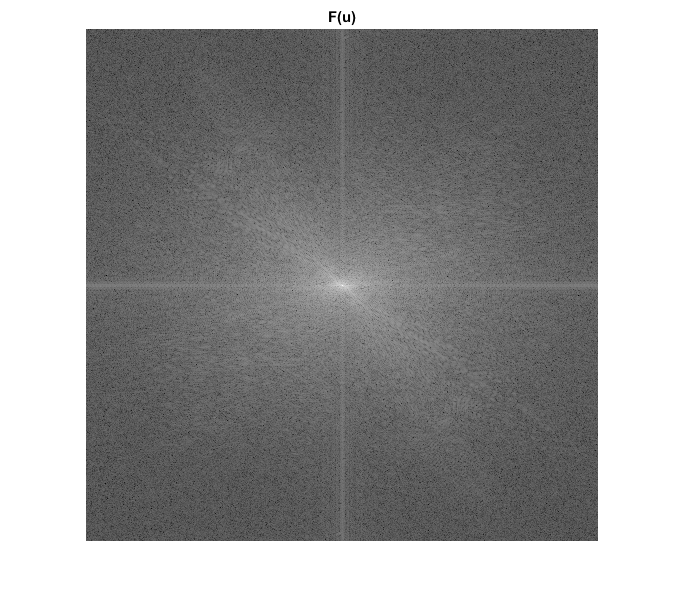


imshow(log(abs(fftshift(fft2(u)))),[]);
title('F(u)');

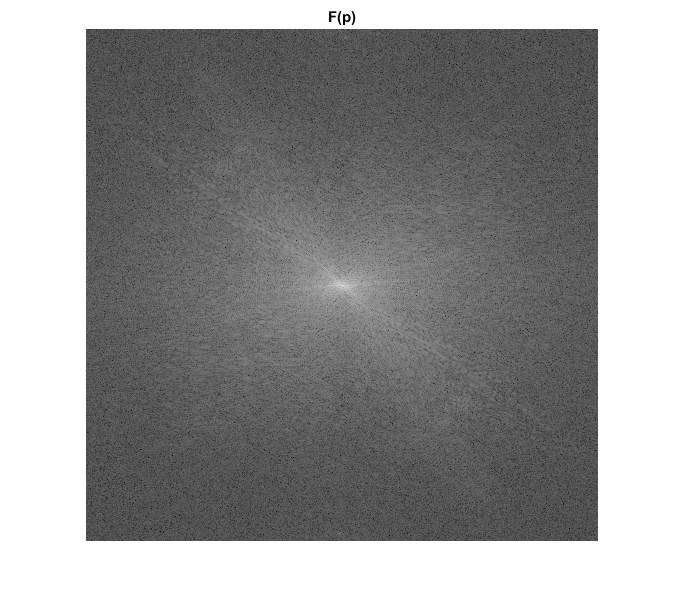

imshow(log(abs(fftshift(fft2(p)))),[]);
title('F(p)');

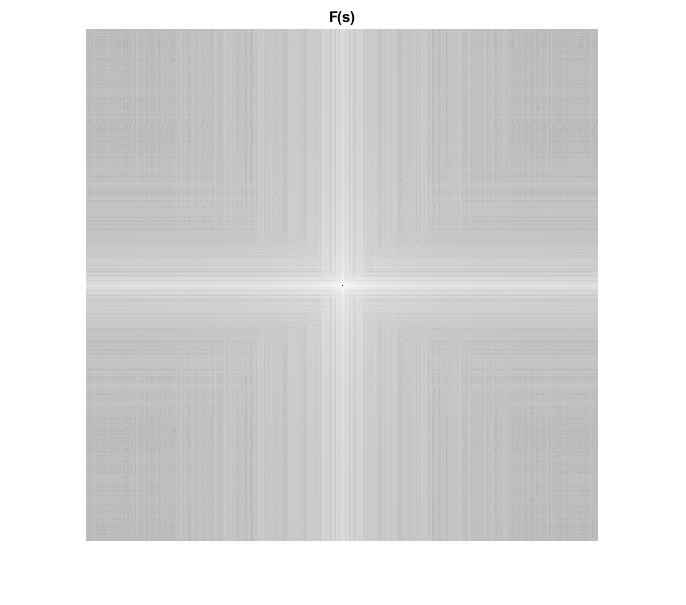

imshow(log(abs(fftshift(fft2(s)))),[]);
title('F(s)');

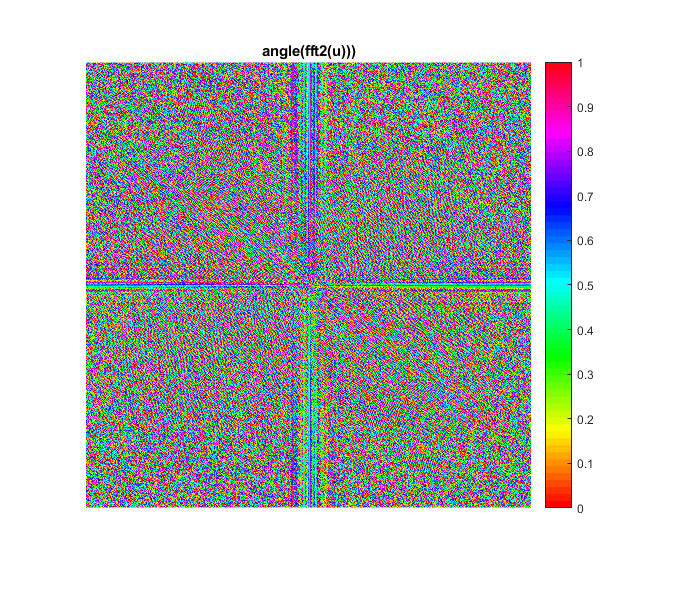


jet_wrap = vertcat(jet,flipud(jet));
imshow(mat2gray(fftshift(angle(fft2(u)))));
colormap(gca,hsv);
colorbar;
title('angle(fft2(u)))');

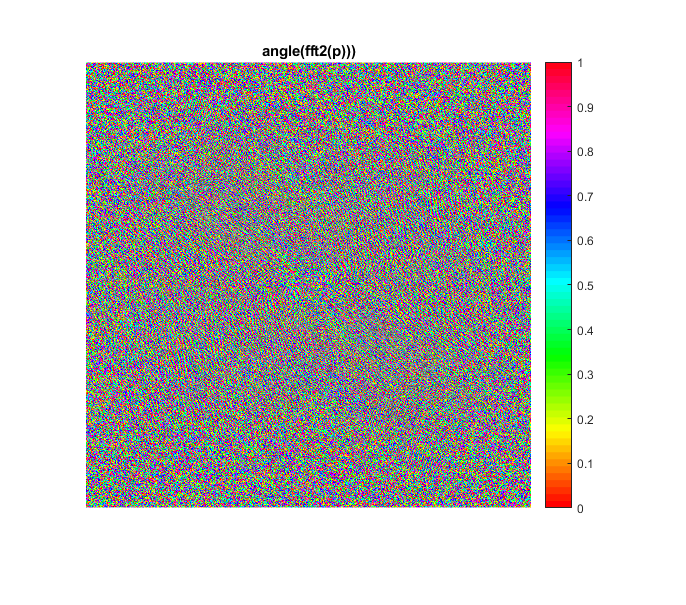


imshow(mat2gray(fftshift(angle(fft2(p)))));
colormap(gca,hsv);
colorbar;
title('angle(fft2(p)))');

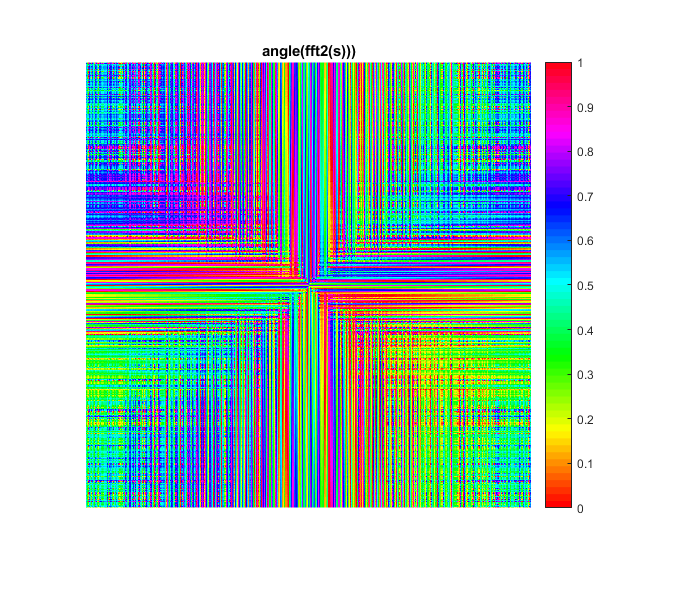


imshow(mat2gray(fftshift(angle(fft2(s)))));
colormap(gca,hsv);
colorbar;
title('angle(fft2(s)))');

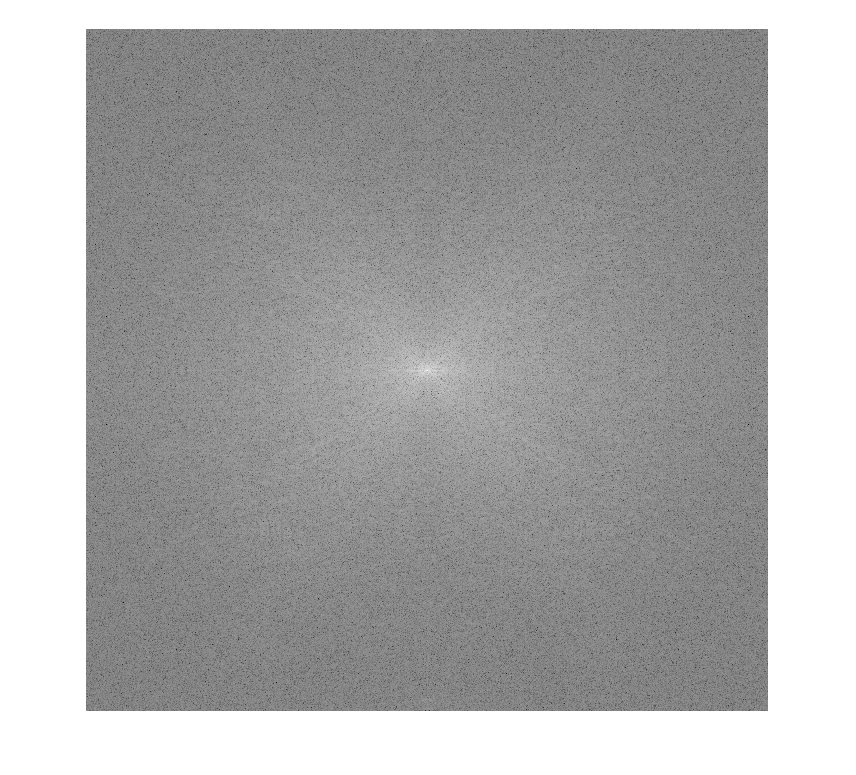


% after p-s decomposition, the artifact in 
% fft2(u) disappeared because discontinuity 
% at boundary is canceled out.

imshow(log(abs(fftshift(fft2(fsym2_per(u))))),[]);

imshow(mat2gray(fftshift(angle(fft2(fsym2_per(u))))));

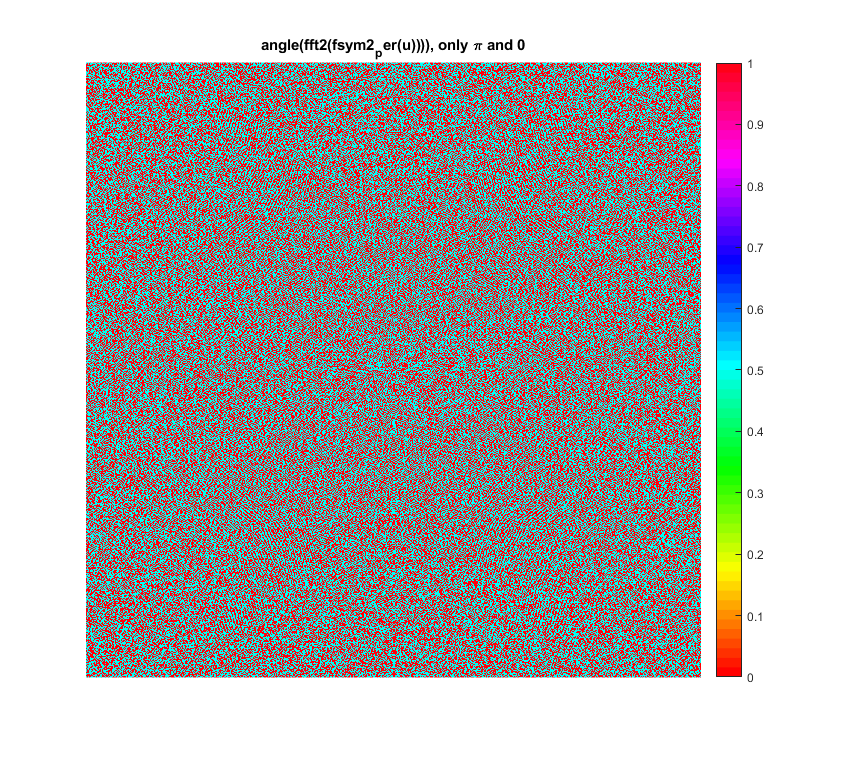

colormap(gca,hsv);
colorbar;
title('angle(fft2(fsym2_per(u)))), only \pi and 0');


% fsym2_per function implements the right way to do 
% sym in matlab, considering the potention periodization
% in DFT

% symmetrization waste time and space. 
% and the phase of fft2(sym(u)) only take two values